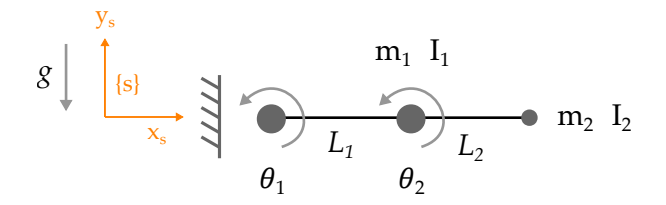

Here we will simulate the dynamics of the planar robot shown above.

We will need to get the $\left(x,y\right)$ position of each link to plot the robot. And we will use the the given simulation parameters and frame rates below:

- **Case 1**: Make a simulation where $\tau =\left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack$ and the robot has no friction, B = 0

% CASE 1: ( tau = [0;0] and B=zeros(2))

close all
clear

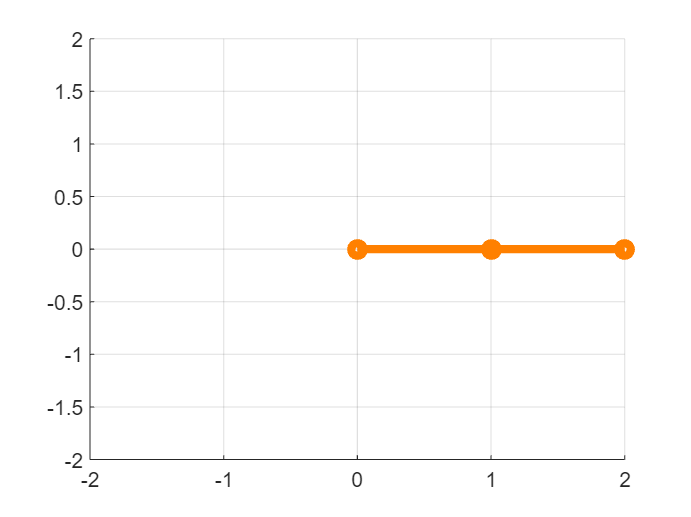

clc


% create figure
figure
axis([-2, 2, -2, 2])
grid on
hold on

% save as a video file
v = VideoWriter('Case_1.mp4', 'MPEG-4');
v.FrameRate = 100;
open(v);

% pick your system parameters
L1 = 1;
L2 = 1;
m1 = 1;
m2 = 1;
I1 = 0.1;
I2 = 0.1;
g = 9.81;
tau = [0;0]; % Case 1

% Initial conditions
theta = [0;0]; % joint position
thetadot = [0;0]; % joint velocity
thetadotdot = [0;0]; % joint acceleration

masses = [m1,m2];
omega = [0;0;1];

Inertia_1 = [0 0 0;0 0 0;0 0 I1];
Inertia_2 = [0 0 0;0 0 0;0 0 I2];

q1 = [0;0;0]; % Position of Joint 1
q2 = [L1;0;0]; % Position of Joint 2
q3 = [L1+L2;0;0]; % end effector position

S1 = [omega; -cross(omega,q1)];
S2 = [omega;-cross(omega,q2)];
S_eq1 = [S1,[0;0;0;0;0;0]];
S_eq2 = [S1, S2]; 

M1 = [eye(3),q2; 0 0 0 1];
M2 = [eye(3), [L1+L2;0;0]; 0 0 0 1];

gravity_vector = (zeros(length(theta),1));
Coriolis_Matrix = (zeros(2,2));
Mass_Matrix = [I1 + I2 + L1^2*m1 + L1^2*m2 + L2^2*m2 + 2*L1*L2*m2*cos(theta(2)), m2*L2^2 + L1*m2*cos(theta(2))*L2 + I2; m2*L2^2 + L1*m2*cos(theta(2))*L2 + I2, m2*L2^2 + I2];
    

for idx = 1:1000

    % plot the robot
    % 1. get the position of each link
    p0 = [0; 0];
    T1 = fk(M1,S_eq2(:,1:1),theta(1:1,:));
    p1 = T1(1:2,4); % position of link 1 (location of joint 2)
    T2 = fk(M2,S_eq2,theta);
    p2 = T2(1:2,4); % position of link 2 (the end-effector)
    P = [p0, p1, p2];
    % 2. draw the robot and save the frame
    cla;
    plot(P(1,:), P(2,:), 'o-', 'color',[1, 0.5, 0],'linewidth',4);
    drawnow;
    frame = getframe(gcf);
    writeVideo(v,frame);

    % integrate to update velocity and position
    % your code here
    deltaT = 0.01;
    thetadot = thetadot + deltaT * thetadotdot;
    theta = theta + deltaT * thetadot;


    Mass_Matrix =[I1 + I2 + L1^2*m1 + L1^2*m2 + L2^2*m2 + 2*L1*L2*m2*cos(theta(2)), m2*L2^2 + L1*m2*cos(theta(2))*L2 + I2; m2*L2^2 + L1*m2*cos(theta(2))*L2 + I2, m2*L2^2 + I2];
    
    Coriolis_Matrix = [-L1*L2*m2*thetadot(2)*sin(theta(2)),  -L1*L2*m2*sin(theta(2))*(thetadot(1) + thetadot(2));L1*L2*m2*thetadot(1)*sin(theta(2)), 0] ;
    
    gravity_vector = [(g*(m1+m2)*L1*cos(theta(1))) + g*m2*L2*cos(theta(1) + theta(2)); g*m2*L2*cos(theta(1) + theta(2))];
    
    B = [[0 0]
        [0 0]]; % Case 1

    thetadotdot = (inv(Mass_Matrix)) * (tau - Coriolis_Matrix * thetadot -B*thetadot - gravity_vector);

    % tau = Mass_Matrix * thetadotdot + Coriolis_Matrix * thetadot + B * thetadot + gravity_vector;

end


close(v);
close all